# RBE502 - HW 9

Read our CSV:

data = readtable('experiment.csv');
data.Properties.VariableNames = {'t', 'q', 'u'};
data

data = 500×3 table
       t            q            u   
    _______    ___________    _______

          0      0.0020401    0.94878
    0.02004     -0.0056486    0.85935
    0.04008      0.0036921    0.86692
    0.06012     -0.0029836    0.86332
    0.08016      0.0036366     1.0349
     0.1002     -0.0014067     1.1356
    0.12024     -0.0048283    0.81042
    0.14028     -0.0054447     1.0262
    0.16032      0.0084905    0.88629
    0.18036       0.011411    0.87117
     0.2004      0.0030553     1.0714
    0.22044    -0.00061999    0.84903
    0.24048    -0.00047594      0.814
    0.26052         0.0172     0.9475
    0.28056      0.0054247    0.83839
     0.3006       0.017514    0.90394


Filter via moving mean

q_filtered = movmean(data.q, 20)

q_filtered =     0.0009
    0.0011
    0.0009
    0.0008
    0.0020
    0.0022
    0.0032
    0.0038
    0.0048
    0.0052


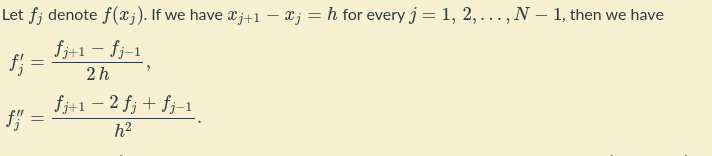

h = data.t(2) - data.t(1)

h = 0.0200


qdot = (q_filtered(3:end)-q_filtered(1:end-2)) / (2*h)

qdot =     0.0013
   -0.0063
    0.0264
    0.0348
    0.0295
    0.0388
    0.0391
    0.0349
    0.0277
    0.0471


qddot = (q_filtered(3:end) - 2*q_filtered(2:end-1) + q_filtered(1:end-2))/(h^2)

qddot =    -0.8441
    0.0822
    3.1828
   -2.3427
    1.8105
   -0.8801
    0.9054
   -1.3205
    0.5957
    1.3462



qdot_filtered = movmean(qdot, 20)

qdot_filtered =     0.0273
    0.0313
    0.0349
    0.0377
    0.0402
    0.0433
    0.0468
    0.0491
    0.0498
    0.0504


qddot_filtered = movmean(qddot, 20)

qddot_filtered =     0.2536
    0.3241
    0.2414
    0.2445
    0.2270
    0.2940
    0.2843
    0.1847
    0.1078
    0.1671



u_filtered = movmean(data.u, 10)

u_filtered =     0.9147
    0.9515
    0.9313
    0.9432
    0.9369
    0.9303
    0.9426
    0.9415
    0.9362
    0.9446



% size(q_filtered)
% size(qdot_filtered)
% size(qddot_filtered)
% size(u_filtered)
% 
% size(q_filtered(2:end-1))
% size(qdot_filtered(1:end))
% size(qddot_filtered(1:end))
% size(u_filtered(2:end-1))

A = [qddot_filtered(1:end) qdot_filtered(1:end)  q_filtered(2:end-1)]

A =     0.2536    0.0273    0.0011
    0.3241    0.0313    0.0009
    0.2414    0.0349    0.0008
    0.2445    0.0377    0.0020
    0.2270    0.0402    0.0022
    0.2940    0.0433    0.0032
    0.2843    0.0468    0.0038
    0.1847    0.0491    0.0048
    0.1078    0.0498    0.0052
    0.1671    0.0504    0.0059


U = u_filtered(2:end-1)

U =     0.9515
    0.9313
    0.9432
    0.9369
    0.9303
    0.9426
    0.9415
    0.9362
    0.9446
    0.9250



theta = (transpose(A)*A)^-1 * transpose(A)*U

theta =     1.5881
    1.5660
   23.2772


Part 3

syms m l
g = 9.81

g = 9.8100

results = solve(theta(1)==m*l^2,theta(3)==m*g*l)

results = struct with fields:
    l: [1×1 sym]
    m: [1×1 sym]


l_calculated = double(results.l)

l_calculated = 0.6693

m_calculated = double(results.m)

m_calculated = 3.5452

Part 4

b_actual = 1.5

b_actual = 1.5000

m_actual = 2.3

m_actual = 2.3000

l_actual = 1.2

l_actual = 1.2000


b_actual - theta(2)

ans = -0.0660

m_actual - m_calculated

ans = -1.2452

l_actual - l_calculated

ans = 0.5307


filters = [4; 10; 20; 50; 100;]

filters =      4
    10
    20
    50
   100



bs = [];
ms = [];
ls = [];

for i = 1:length(filters)
    disp("================================")
    filter = filters(i)
    
    q_filtered = movmean(data.q, filter);
    qdot = (q_filtered(3:end)-q_filtered(1:end-2)) / (2*h);
    qddot = (q_filtered(3:end) - 2*q_filtered(2:end-1) + q_filtered(1:end-2))/(h^2);
    
    qdot_filtered = movmean(qdot, filter);
    qddot_filtered = movmean(qddot, filter);
    
    u_filtered = movmean(data.u, filter/2);
    
    A = [qddot_filtered(1:end) qdot_filtered(1:end)  q_filtered(2:end-1)];
    U = u_filtered(2:end-1);

    theta = (transpose(A)*A)^-1 * transpose(A)*U;
    
    results = solve(theta(1)==m*l^2,theta(3)==m*g*l);
    l_calculated = double(results.l);
    m_calculated = double(results.m);
    
    bs = [bs theta(2)];
    ms = [ms m_calculated];
    ls = [ls l_calculated];
    
    disp("b")
    theta(2)
    b_actual - theta(2)
    disp("l")
    double(results.l)
    l_actual - l_calculated
    disp("m")
    double(results.m)
    m_actual - m_calculated
    disp("================================")
end

filter = 4

b


ans = 0.6607

ans = 0.8393

l


ans = 0.0069

ans = 1.1931

m


ans = 290.1364

ans = -287.8364

filter = 10

b


ans = 1.5420

ans = -0.0420

l


ans = 0.1015

ans = 1.0985

m


ans = 20.2310

ans = -17.9310

filter = 20

b


ans = 1.5660

ans = -0.0660

l


ans = 0.6693

ans = 0.5307

m


ans = 3.5452

ans = -1.2452

filter = 50

b


ans = 2.2413

ans = -0.7413

l


ans = 1.5986

ans = -0.3986

m


ans = 1.8306

ans = 0.4694

filter = 100

b


ans = 2.1282

ans = -0.6282

l


ans = -0.8629

ans = 2.0629

m


ans = -2.9001

ans = 5.2001

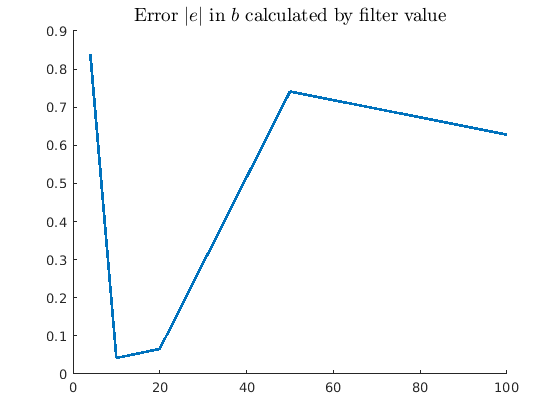

% ======================

figure
title("Error $|e|$ in $b$ calculated by filter value", 'Interpreter', 'latex', "FontSize", 14);
hold on;

plot(filters, abs(b_actual-bs), 'Linewidth', 2)

hold off;
exportgraphics(gcf,'figures/filter_b_error.png','Resolution',300)

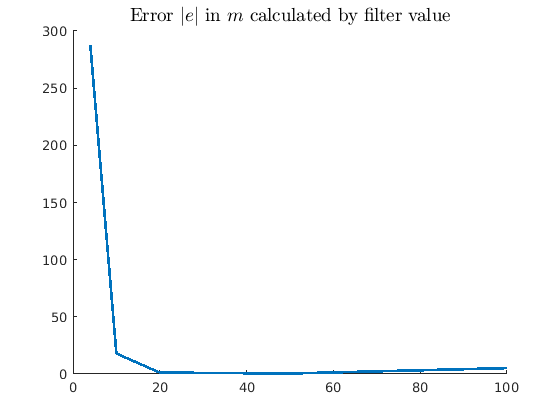


% ======================

figure
title("Error $|e|$ in $m$ calculated by filter value", 'Interpreter', 'latex', "FontSize", 14);
hold on;

plot(filters, abs(m_actual-ms), 'Linewidth', 2)

hold off;
exportgraphics(gcf,'figures/filter_m_error.png','Resolution',300)


% ======================

tmp = abs(m_actual-ms)

tmp =   287.8364   17.9310    1.2452    0.4694    5.2001


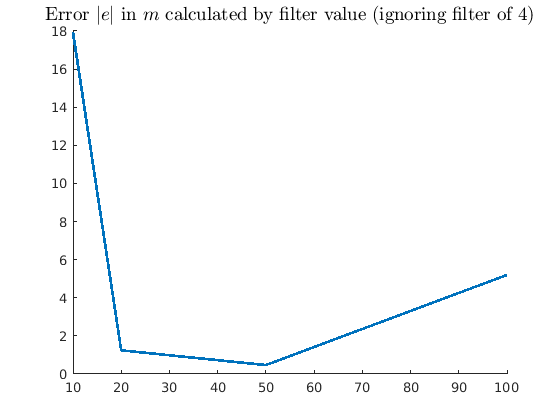

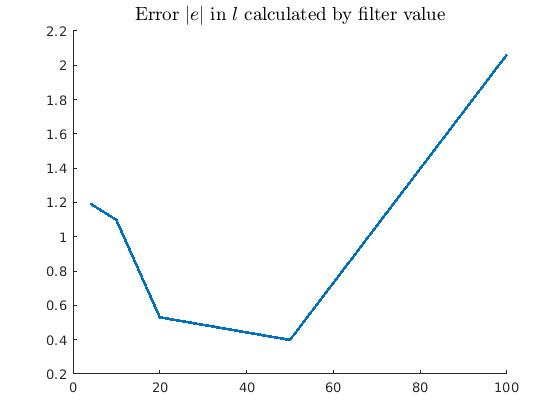

figure
title("Error $|e|$ in $m$ calculated by filter value (ignoring filter of $4$)", 'Interpreter', 'latex', "FontSize", 14);
hold on;

plot(filters(2:end), tmp(2:end), 'Linewidth', 2)

hold off;

exportgraphics(gcf,'figures/filter_m_error_2.png','Resolution',300)

% ======================

figure
title("Error $|e|$ in $l$ calculated by filter value", 'Interpreter', 'latex', "FontSize", 14);
hold on;

plot(filters, abs(l_actual-ls), 'Linewidth', 2)

hold off;
exportgraphics(gcf,'figures/filter_l_error.png','Resolution',300)


% ======================

% Basic diff

q_filtered = movmean(data.q, 20);

h = data.t(2) - data.t(1);

qdot_filtered = movmean(diff(qdot), 20);
qddot_filtered = movmean(diff(qdot_filtered), 20);

u_filtered = movmean(data.u, 10);
size(qddot_filtered(1:end))

ans =    496     1


size(qdot_filtered(2:end))

ans =    496     1


size(q_filtered(3:end-2))

ans =    496     1


A = [qddot_filtered(1:end) qdot_filtered(2:end)  q_filtered(3:end-2)];
U = u_filtered(3:end-2);

theta = (transpose(A)*A)^-1 * transpose(A)*U;
syms m l
g = 9.81;
results = solve(theta(1)==m*l^2,theta(3)==m*g*l);
theta(2)

ans = -277.2780

l_calculated = double(results.l)

l_calculated = 464.1597

m_calculated = double(results.m)

m_calculated = 0.0035



% (x+1 - x / x)/h

q_filtered = movmean(data.q, 20)

q_filtered =     0.0009
    0.0011
    0.0009
    0.0008
    0.0020
    0.0022
    0.0032
    0.0038
    0.0048
    0.0052



qdot_filtered = movmean((q_filtered(2:end)-q_filtered(1:end-1))/h, 20)

qdot_filtered =     0.0248
    0.0281
    0.0325
    0.0352
    0.0379
    0.0403
    0.0439
    0.0473
    0.0487
    0.0487


qddot_filtered = movmean((qdot_filtered(2:end)-qdot_filtered(1:end-1))/h, 20)

qddot_filtered =     0.1254
    0.1269
    0.1434
    0.1558
    0.1499
    0.1525
    0.1481
    0.1495
    0.1432
    0.1443



size(q_filtered(3:end))

ans =    498     1


size(qdot_filtered(2:end))

ans =    498     1


size(qddot_filtered(1:end))

ans =    498     1



A = [qddot_filtered(1:end) qdot_filtered(2:end)  q_filtered(3:end)];
U = u_filtered(3:end);

theta = (transpose(A)*A)^-1 * transpose(A)*U;
syms m l
g = 9.81;
results = solve(theta(1)==m*l^2,theta(3)==m*g*l);
theta

theta =     3.8581
    0.9141
   27.7229


l_calculated = double(results.l)

l_calculated = 1.3652

m_calculated = double(results.m)

m_calculated = 2.0700


b_actual - theta(2)

ans = 0.5859

l_actual-l_calculated

ans = -0.1652

m_actual-m_calculated

ans = 0.2300